# ME5411 | Task 1–6 现有代码展示

代码、参数与输入/输出对照。来源：ME5411-Project/CoreCode，原始 main aeafa6d69949f4dc7aa8ee0145483e18fb5b7695。 本文件组织既有代码用于展示，不选择最优参数、不新增算法；观察、分析与推理由小组填写。 点击 Run 从头运行。计算会写本轮临时目录；查看结果后，在末尾“保存本次实验”节选择是否归档，默认不归档。 修改参数：各小节开头标为“参数”的赋值行；下列数值全部取自 CoreCode 原稿。 输入关系：原图 → Task 1；原图 → Task 2；原图 → Task 3 → Task 4 → Task 5 / Task 6。 Task 1、2 的输出不传给 Task 3；Task 6 不使用 Task 5 的轮廓图。 GUI 与 CoreCode 是两套入口。本展示取 CoreCode 的所有现有方法；Task 5 连接窗口 n=5，GUI 默认为 3。 首次运行或修改上游参数后，请从头运行。仅重跑后续小节会使用当前工作区的上游结果。

demoExperimentState = struct('Completed',false); % 新一轮先使旧结果失效。
notebookRoot = fileparts(mfilename('fullpath'));
if ~isfile(fullfile(notebookRoot,'..','dataset_2026','Test_Image_2026.bmp'))
    notebookRoot = fileparts(which('ME5411_Task1to6_Demo.mlx'));
end
if ~isfile(fullfile(notebookRoot,'..','dataset_2026','Test_Image_2026.bmp'))
    notebookRoot = pwd; % Live Editor 可能在临时目录执行；从 LiveDemo 文件夹运行。
end
assert(isfile(fullfile(notebookRoot,'..','dataset_2026','Test_Image_2026.bmp')), ...
    '请将 MATLAB 当前文件夹设为 live-demo 后运行。');
addpath(notebookRoot);
demoExperimentState = me5411_experiment('start',notebookRoot,fullfile(notebookRoot,'..','dataset_2026','Test_Image_2026.bmp'));
runRoot = demoExperimentState.WorkDir;
inputPath = fullfile(runRoot,'input','Test_Image_2026.bmp'); % 本轮输入快照。
originalImage = imread(inputPath);
% 以下灰度转换与 CoreCode 一致；仅将输入变量保存为 originalImage。
if ndims(originalImage) == 3
    rgb = double(originalImage);
    originalImage = uint8(round(0.298936021293775 * rgb(:, :, 1) + ...
        0.587043074451121 * rgb(:, :, 2) + 0.114020904255103 * rgb(:, :, 3)));
end
assert(ismatrix(originalImage) && isa(originalImage,'uint8'));
demoResults = struct;
demoParameters = struct;
demoLog = struct('Task',{},'Method',{},'InputSize',{},'OutputSize',{},'Status',{});
fprintf('Input: %d rows x %d columns. Temporary run: %s\n',size(originalImage,1),size(originalImage,2),demoExperimentState.RunId);

Input: 367 rows x 990 columns. Temporary run: tp936ba4ae_df2e_46f4_b53c_9f74e111d86a


## Task 1.1 | Contrast Stretching

% 分段映射灰度；r1、r2 是输入转折点，s1、s2 是对应的输出灰度。

% 来源：CoreCode/Task1_ContrastStretching.m；以下参数和计算语句保持原稿。

demoExperimentState = me5411_experiment('step',demoExperimentState,1);

I = originalImage; % 每个方法独立读取原图对应的灰度数组。

% 参数（在这里修改；当前为原默认值）
r1 = 80;
r2 = 140;
s1 = 30;
s2 = 220;

demoParameters.ContrastStretching = struct('r1',r1,'r2',r2,'s1',s1,'s2',s2);

r = double(I);
J = zeros(size(I));
low = r <= r1; middle = r > r1 & r <= r2; high = r > r2;
J(low) = s1 * r(low) / r1;
J(middle) = s1 + (s2-s1) * (r(middle)-r1) / (r2-r1);
J(high) = s2 + (255-s2) * (r(high)-r2) / (255-r2);
J = uint8(round(min(max(J, 0), 255)));

demoResults.ContrastStretching = J;

demoLog(end+1) = recordResult(runRoot,'Task1','ContrastStretching',I,J);

Task1 / ContrastStretching: [367 990] -> [367 990]; completed.


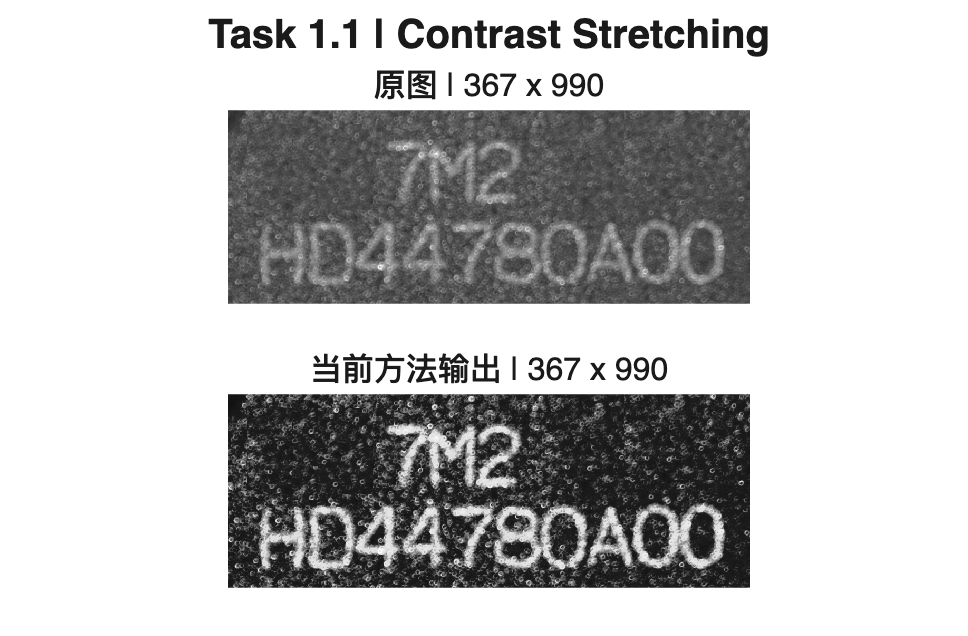


compareImages(I,J,'Task 1.1 | Contrast Stretching',{'原图','当前方法输出'},fullfile(runRoot,'ContrastStretching_comparison.png'));


% 小组观察：________________　小组解释：________________

## Task 1.2 | Gray-Level Slicing

% A、B 定义保留的灰度区间，s_in 为区间内值，s_out 为区间外值；原码也支持 s_out='r' 保留背景。

% 来源：CoreCode/Task1_GrayLevelSlicing.m；以下参数和计算语句保持原稿。

demoExperimentState = me5411_experiment('step',demoExperimentState,2);

I = originalImage; % 每个方法独立读取原图对应的灰度数组。

% 参数（在这里修改；当前为原默认值）
A = 80;
B = 140;
s_in = 255;
s_out = 0;

demoParameters.GrayLevelSlicing = struct('A',A,'B',B,'s_in',s_in,'s_out',s_out);

if isequal(s_out, 'r')
    J = I;
else
    J = repmat(uint8(s_out), size(I));
end
J(I >= A & I <= B) = s_in;

demoResults.GrayLevelSlicing = J;

demoLog(end+1) = recordResult(runRoot,'Task1','GrayLevelSlicing',I,J);

Task1 / GrayLevelSlicing: [367 990] -> [367 990]; completed.


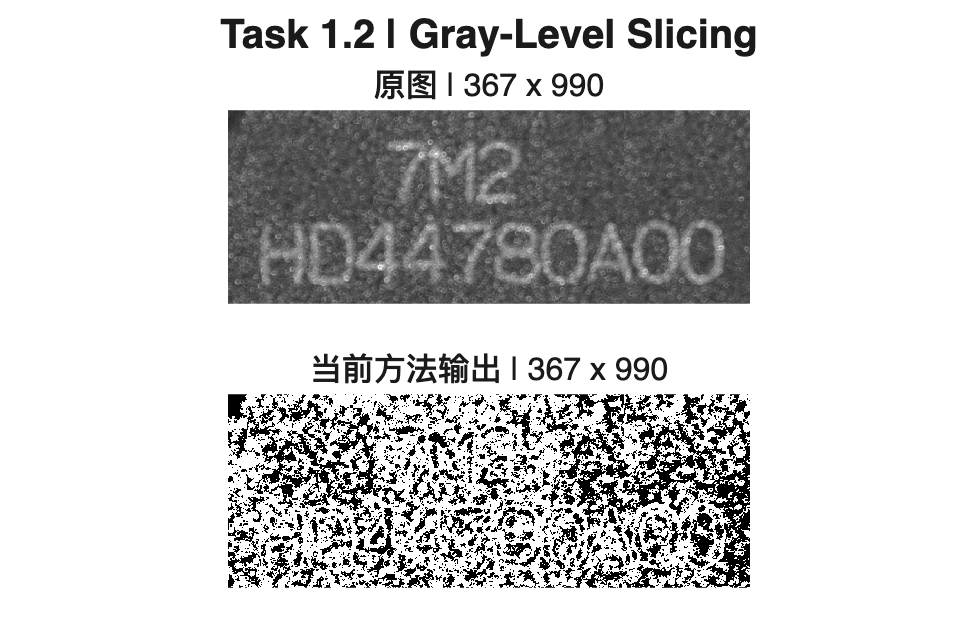


compareImages(I,J,'Task 1.2 | Gray-Level Slicing',{'原图','当前方法输出'},fullfile(runRoot,'GrayLevelSlicing_comparison.png'));


% 小组观察：________________　小组解释：________________

## Task 1.3 | Dynamic Range Compression

% c 是对数映射系数；本次保留原码的 255/log(256)。

% 来源：CoreCode/Task1_DynamicRangeCompression.m；以下参数和计算语句保持原稿。

demoExperimentState = me5411_experiment('step',demoExperimentState,3);

I = originalImage; % 每个方法独立读取原图对应的灰度数组。

% 参数（在这里修改；当前为原默认值）
c = 255 / log(256);

demoParameters.DynamicRangeCompression = struct('c',c);

J = uint8(c * log1p(double(I)));

demoResults.DynamicRangeCompression = J;

demoLog(end+1) = recordResult(runRoot,'Task1','DynamicRangeCompression',I,J);

Task1 / DynamicRangeCompression: [367 990] -> [367 990]; completed.


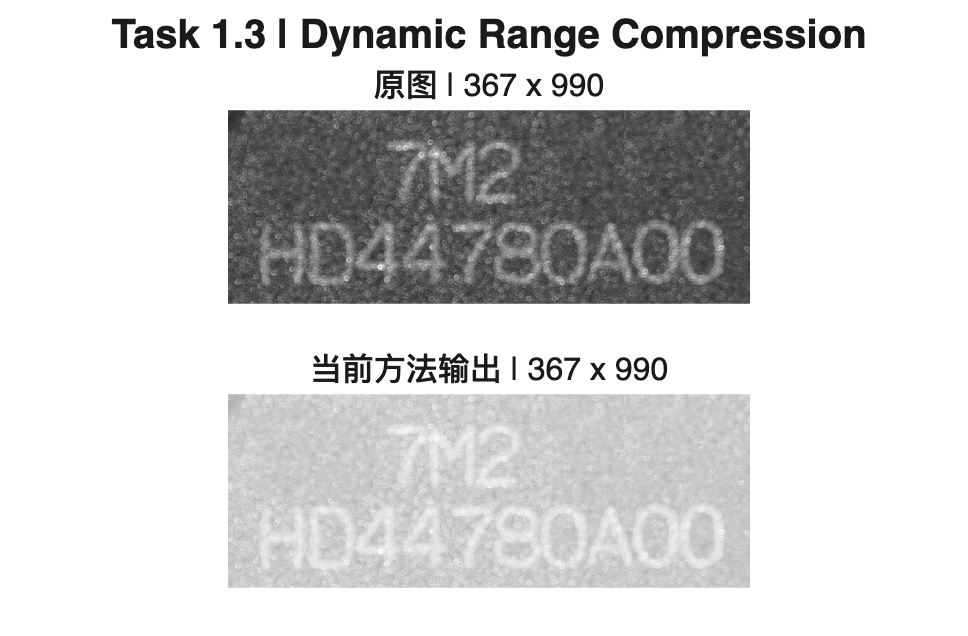


compareImages(I,J,'Task 1.3 | Dynamic Range Compression',{'原图','当前方法输出'},fullfile(runRoot,'DynamicRangeCompression_comparison.png'));


% 小组观察：________________　小组解释：________________

## Task 1.4 | Histogram Equalization

% 原码以灰度计数的累积和建立映射；没有用户可调参数。

% 来源：CoreCode/Task1_HistogramEqualization.m；以下参数和计算语句保持原稿。

demoExperimentState = me5411_experiment('step',demoExperimentState,4);

I = originalImage; % 每个方法独立读取原图对应的灰度数组。

demoParameters.HistogramEqualization = struct;

counts = accumarray(double(I(:)) + 1, 1, [256 1]);
mapping = uint8(255 * cumsum(counts) / numel(I));
J = reshape(mapping(double(I(:)) + 1), size(I));

demoResults.HistogramEqualization = J;

demoLog(end+1) = recordResult(runRoot,'Task1','HistogramEqualization',I,J);

Task1 / HistogramEqualization: [367 990] -> [367 990]; completed.


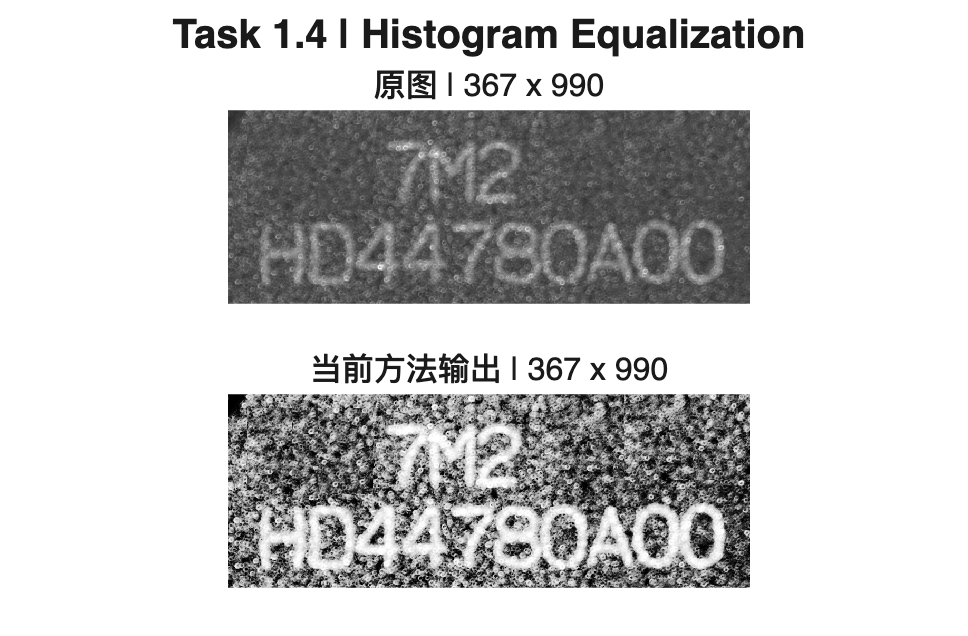


compareImages(I,J,'Task 1.4 | Histogram Equalization',{'原图','当前方法输出'},fullfile(runRoot,'HistogramEqualization_comparison.png'));


% 小组观察：________________　小组解释：________________

## Task 2.1 | Mean Filtering

% n 是邻域边长，默认 5；边界复制与积分和计算沿用原码。

% 来源：CoreCode/Task2_MeanFiltering.m；以下参数和计算语句保持原稿。

demoExperimentState = me5411_experiment('step',demoExperimentState,5);

I = originalImage; % 每个方法独立读取原图对应的灰度数组。

% 参数（在这里修改；当前为原默认值）
n = 5;

demoParameters.MeanFiltering = struct('n',n);

[h, w] = size(I);
r = (n - 1) / 2;
P = I(min(max((1-r):(h+r), 1), h), min(max((1-r):(w+r), 1), w));
S = makeSummedArea(double(P));
J = uint8(round(squareWindowSums(S, n) / n^2));

demoResults.MeanFiltering = J;

demoLog(end+1) = recordResult(runRoot,'Task2','MeanFiltering',I,J);

Task2 / MeanFiltering: [367 990] -> [367 990]; completed.


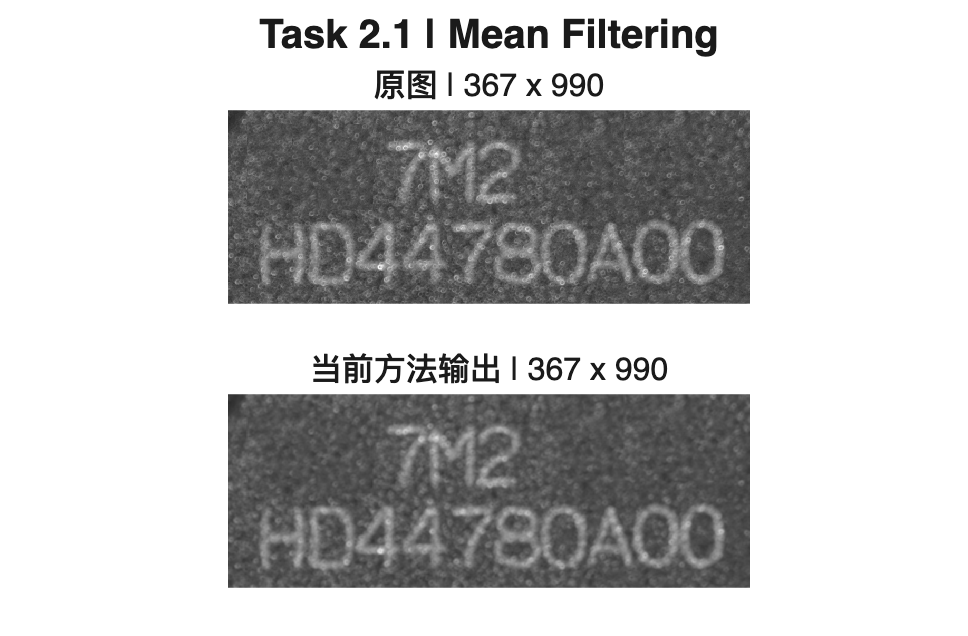


compareImages(I,J,'Task 2.1 | Mean Filtering',{'原图','当前方法输出'},fullfile(runRoot,'MeanFiltering_comparison.png'));


% 小组观察：________________　小组解释：________________

## Task 2.2 | Rotating Mask

% n 是外层窗口边长；m、offsets 由原码计算，score 用于在现有候选窗口中选择。

% 来源：CoreCode/Task2_RotatingMask.m；以下参数和计算语句保持原稿。

demoExperimentState = me5411_experiment('step',demoExperimentState,6);

I = originalImage; % 每个方法独立读取原图对应的灰度数组。

% 参数（在这里修改；当前为原默认值）
n = 5;

demoParameters.RotatingMask = struct('n',n);

m = min(n, 2 * floor((n + 1) / 4) + 1);
d = (n - m) / 2;
offsets = [d d; 0 0; 0 d; 0 2*d; d 0; d 2*d; 2*d 0; 2*d d; 2*d 2*d];
[h, w] = size(I);
r = (n - 1) / 2;
P = I(min(max((1-r):(h+r), 1), h), min(max((1-r):(w+r), 1), w));
P = double(P);
S = squareWindowSums(makeSummedArea(P), m);
Q = squareWindowSums(makeSummedArea(P.^2), m);
best = inf(size(I));
J = zeros(size(I));
for k = 1:9
    rows = (1:size(I, 1)) + offsets(k, 1);
    cols = (1:size(I, 2)) + offsets(k, 2);
    sums = S(rows, cols);
    score = m^2 * Q(rows, cols) - sums.^2;
    selected = score < best;
    best(selected) = score(selected);
    J(selected) = sums(selected) / m^2;
end
J = uint8(J);

demoResults.RotatingMask = J;

demoLog(end+1) = recordResult(runRoot,'Task2','RotatingMask',I,J);

Task2 / RotatingMask: [367 990] -> [367 990]; completed.


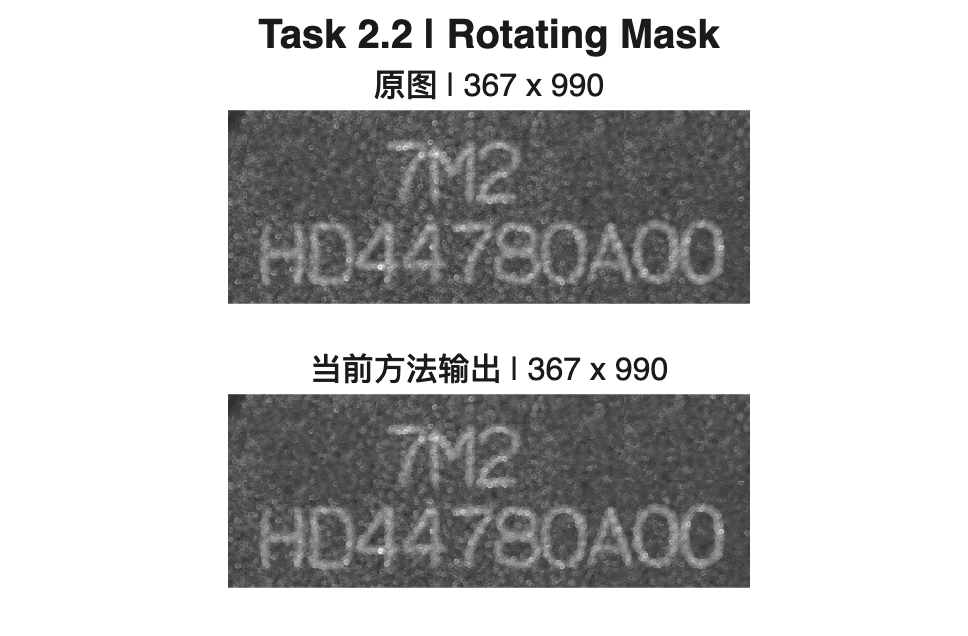


compareImages(I,J,'Task 2.2 | Rotating Mask',{'原图','当前方法输出'},fullfile(runRoot,'RotatingMask_comparison.png'));


% 小组观察：________________　小组解释：________________

## Task 2.3 | Median Filtering

% n 是邻域边长，默认 5；逐列更新直方图，依据 medianRank 取窗口中值。

% 来源：CoreCode/Task2_MedianFiltering.m；以下参数和计算语句保持原稿。

demoExperimentState = me5411_experiment('step',demoExperimentState,7);

I = originalImage; % 每个方法独立读取原图对应的灰度数组。

% 参数（在这里修改；当前为原默认值）
n = 5;

demoParameters.MedianFiltering = struct('n',n);

[h, w] = size(I);
r = (n - 1) / 2;
P = I(min(max((1-r):(h+r), 1), h), min(max((1-r):(w+r), 1), w));
minimumGray = double(min(P(:)));
maximumGray = double(max(P(:)));
numberOfBins = maximumGray - minimumGray + 1;
numberOfRows = size(P, 1);
rowIndices = (1:numberOfRows).';
rowHistograms = zeros(numberOfRows, numberOfBins, 'single');
for column = 1:n
    indices = rowIndices + numberOfRows * (double(P(:, column)) - minimumGray);
    rowHistograms(indices) = rowHistograms(indices) + 1;
end
medianRank = (n^2 + 1) / 2;
J = zeros(h, w, 'uint8');
for column = 1:w
    verticalSums = [zeros(1, numberOfBins, 'single'); cumsum(rowHistograms, 1)];
    windowHistograms = verticalSums((n + 1):end, :) ...
        - verticalSums(1:(end - n), :);
    cumulativeCounts = cumsum(windowHistograms, 2);
    J(:, column) = uint8(minimumGray + sum(cumulativeCounts < medianRank, 2));
    if column < w
        outgoing = rowIndices + numberOfRows * ...
            (double(P(:, column)) - minimumGray);
        incoming = rowIndices + numberOfRows * ...
            (double(P(:, column + n)) - minimumGray);
        rowHistograms(outgoing) = rowHistograms(outgoing) - 1;
        rowHistograms(incoming) = rowHistograms(incoming) + 1;
    end
end

demoResults.MedianFiltering = J;

demoLog(end+1) = recordResult(runRoot,'Task2','MedianFiltering',I,J);

Task2 / MedianFiltering: [367 990] -> [367 990]; completed.


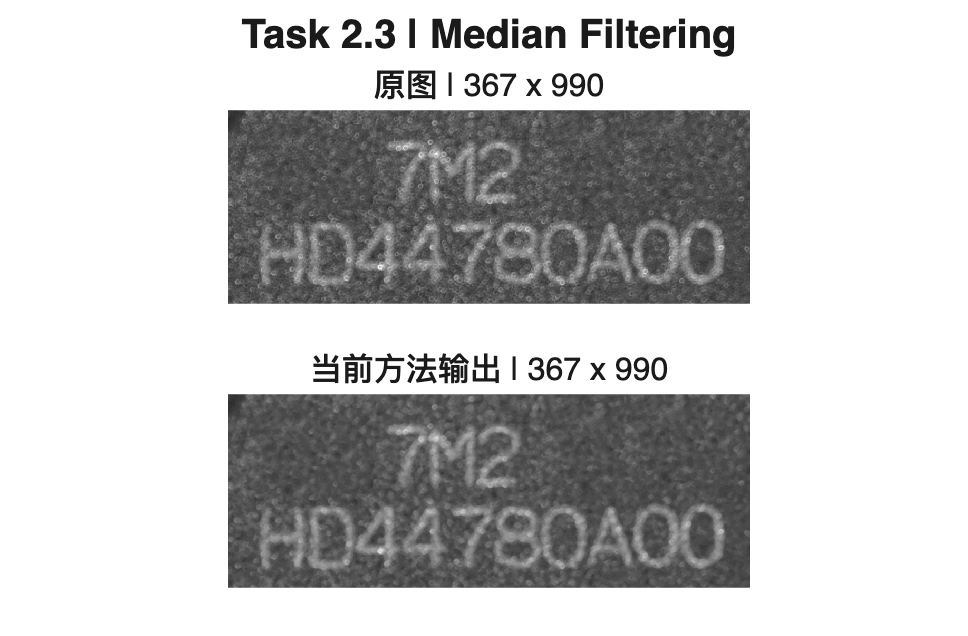


compareImages(I,J,'Task 2.3 | Median Filtering',{'原图','当前方法输出'},fullfile(runRoot,'MedianFiltering_comparison.png'));


% 小组观察：________________　小组解释：________________

## Task 3 | Sub-image Extraction

% x 为列坐标，y 为行坐标；MATLAB 索引从 1 开始且包含两端。裁剪直接使用原图。

% 来源：CoreCode/Task3.m；以下参数和计算语句保持原稿。

demoExperimentState = me5411_experiment('step',demoExperimentState,8);

I = originalImage;
% 参数（在这里修改）
x1 = 56;
y1 = 201;
x2 = 946;
y2 = 341;

demoParameters.Crop = struct('x1',x1,'y1',y1,'x2',x2,'y2',y2);

J = I(y1:y2, x1:x2);

cropImage = J;

demoResults.Crop = J;

demoLog(end+1) = recordResult(runRoot,'Task3','Crop',I,J);

Task3 / Crop: [367 990] -> [141 891]; completed.


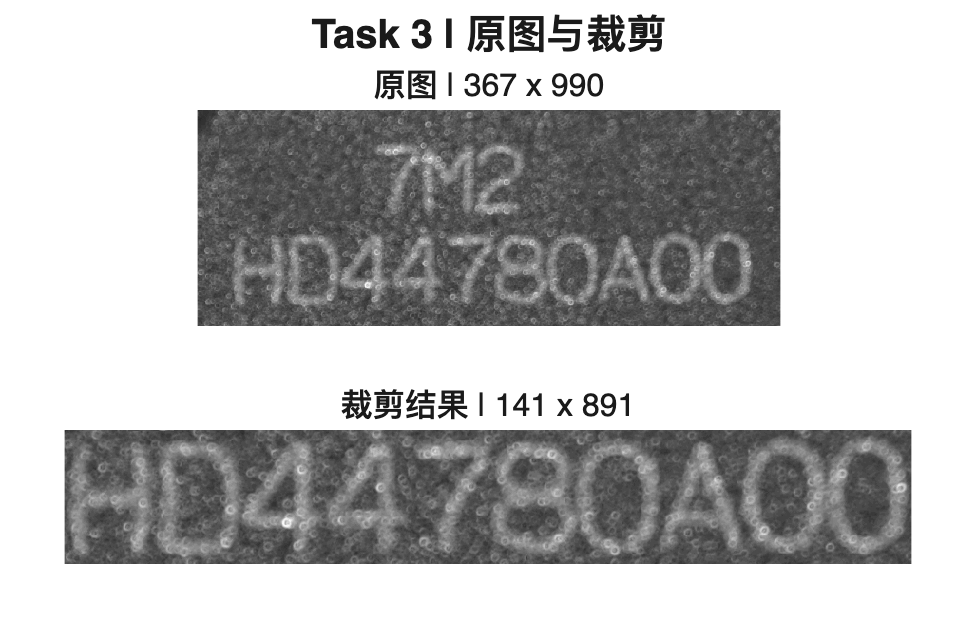


compareImages(I,J,'Task 3 | 原图与裁剪',{'原图','裁剪结果'},fullfile(runRoot,'Crop_comparison.png'));


% 小组观察：________________　小组解释：________________

## Task 4 | Binarization

% 输入是本次 Task 3 的裁剪结果；threshold 是灰度阈值，原判断为严格大于。

% 来源：CoreCode/Task4.m；以下参数和计算语句保持原稿。

demoExperimentState = me5411_experiment('step',demoExperimentState,9);

I = imread(fullfile(runRoot,'Crop.png')); % 实际读取本次 Task 3 输出，保持文件依赖。
% 参数（在这里修改）
threshold = 128;

demoParameters.Binarization = struct('threshold',threshold);

J = I > threshold;

binaryImage = J;

demoResults.Binarization = J;

demoLog(end+1) = recordResult(runRoot,'Task4','Binarization',I,J);

Task4 / Binarization: [141 891] -> [141 891]; completed.


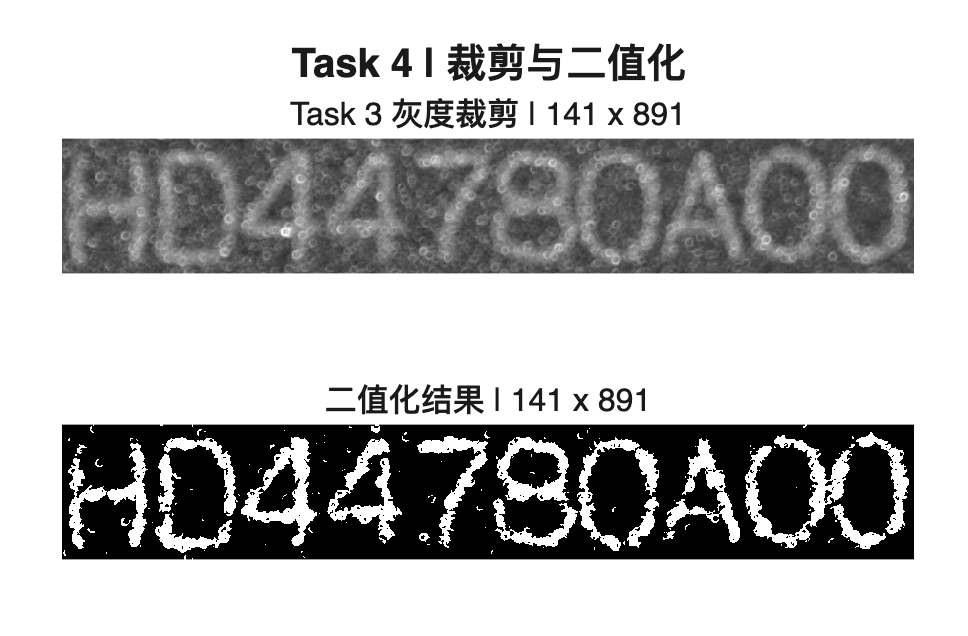


compareImages(I,J,'Task 4 | 裁剪与二值化',{'Task 3 灰度裁剪','二值化结果'},fullfile(runRoot,'Binarization_comparison.png'));


% 小组观察：________________　小组解释：________________

## Task 5 | TwoPass

% 比较水平和垂直相邻像素，合并不同值的位置；没有可调参数。 本节三个方法分别使用 Task 4 二值图，不互相串联。

% 来源：CoreCode/Task5_TwoPass.m；以下参数和计算语句保持原稿。

demoExperimentState = me5411_experiment('step',demoExperimentState,10);

I = imread(fullfile(runRoot,'Binarization.png')) ~= 0;

demoParameters.TwoPass = struct;

J = false(size(I));
J(:, 2:end) = I(:, 2:end) ~= I(:, 1:end-1);
J(2:end, :) = J(2:end, :) | I(2:end, :) ~= I(1:end-1, :);

demoResults.TwoPass = J;

demoLog(end+1) = recordResult(runRoot,'Task5','TwoPass',I,J);

Task5 / TwoPass: [141 891] -> [141 891]; completed.


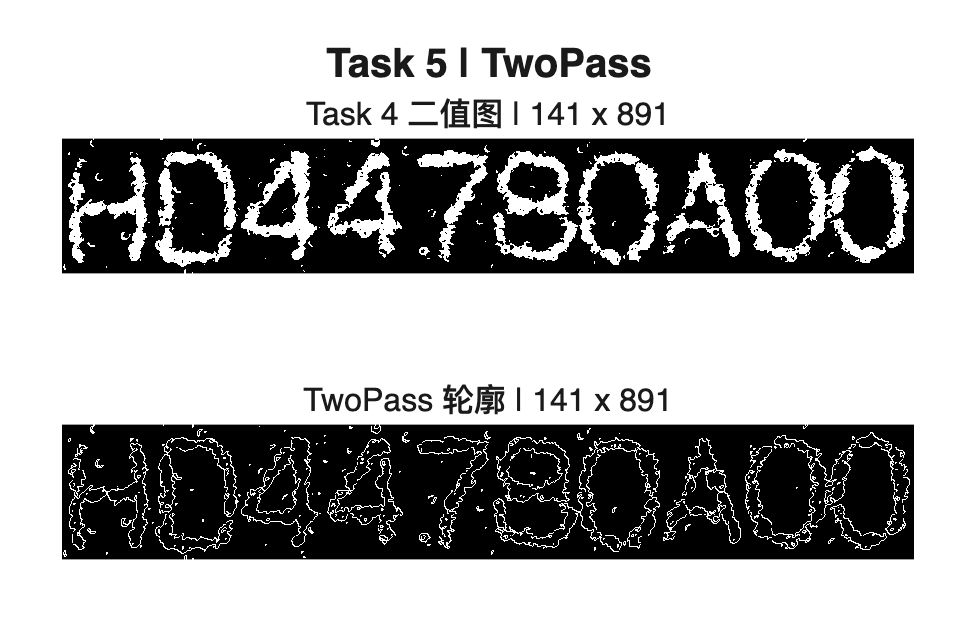


compareImages(I,J,'Task 5 | TwoPass',{'Task 4 二值图','TwoPass 轮廓'},fullfile(runRoot,'TwoPass_comparison.png'));


% 小组观察：________________　小组解释：________________

## Task 5 | Sobel

% threshold 是归一化梯度幅值的阈值，默认 0.2。 本节三个方法分别使用 Task 4 二值图，不互相串联。

% 来源：CoreCode/Task5_Sobel.m；以下参数和计算语句保持原稿。

demoExperimentState = me5411_experiment('step',demoExperimentState,11);

I = imread(fullfile(runRoot,'Binarization.png')) ~= 0;

% 参数（在这里修改）
threshold = 0.2;

demoParameters.Sobel = struct('threshold',threshold);

[h, w] = size(I);
P = double(I([1, 1:h, h], [1, 1:w, w]));
Gy = conv2(P, [1 2 1; 0 0 0; -1 -2 -1], 'valid');
Gx = conv2(P, [1 0 -1; 2 0 -2; 1 0 -1], 'valid');
M = min(1, hypot(Gx, Gy) / (4 * sqrt(2)));
J = M > threshold;

demoResults.Sobel = J;

demoLog(end+1) = recordResult(runRoot,'Task5','Sobel',I,J);

Task5 / Sobel: [141 891] -> [141 891]; completed.


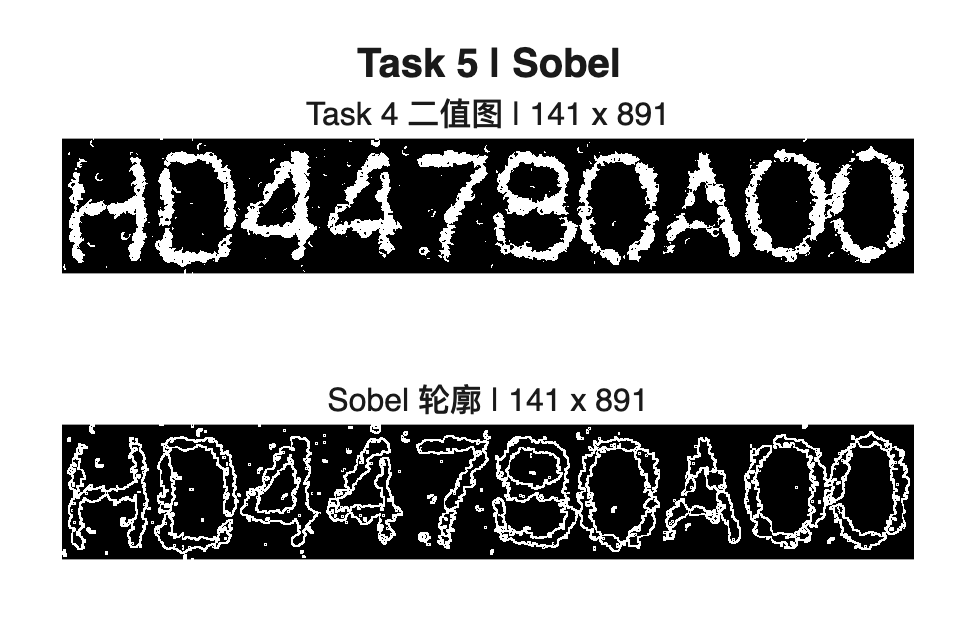


compareImages(I,J,'Task 5 | Sobel',{'Task 4 二值图','Sobel 轮廓'},fullfile(runRoot,'Sobel_comparison.png'));


% 小组观察：________________　小组解释：________________

## Task 5 | Laplacian

% threshold 用于原码零交叉强度条件，默认 0.2。 本节三个方法分别使用 Task 4 二值图，不互相串联。

% 来源：CoreCode/Task5_Laplacian.m；以下参数和计算语句保持原稿。

demoExperimentState = me5411_experiment('step',demoExperimentState,12);

I = imread(fullfile(runRoot,'Binarization.png')) ~= 0;

% 参数（在这里修改）
threshold = 0.2;

demoParameters.Laplacian = struct('threshold',threshold);

[h, w] = size(I);
P = double(I([1, 1:h, h], [1, 1:w, w]));
L = conv2(P, [0 -1 0; -1 4 -1; 0 -1 0], 'valid');
[h, w] = size(I);
J = false(h, w);
offsets = [0 1; 1 -1; 1 0; 1 1];
for k = 1:4
    dy = offsets(k, 1); dx = offsets(k, 2);
    r = max(1, 1-dy):min(h, h-dy);
    c = max(1, 1-dx):min(w, w-dx);
    a = L(r, c); b = L(r+dy, c+dx);
    crossing = a .* b < 0 & abs(a-b) > 8 * threshold;
    J(r, c) = J(r, c) | (crossing & abs(a) <= abs(b));
    J(r+dy, c+dx) = J(r+dy, c+dx) | (crossing & abs(a) > abs(b));
    r = 1+abs(dy):h-abs(dy); c = 1+abs(dx):w-abs(dx);
    a = L(r-dy, c-dx); b = L(r+dy, c+dx);
    J(r, c) = J(r, c) | (L(r, c) == 0 & a .* b < 0 & abs(a-b) > 8 * threshold);
end

demoResults.Laplacian = J;

demoLog(end+1) = recordResult(runRoot,'Task5','Laplacian',I,J);

Task5 / Laplacian: [141 891] -> [141 891]; completed.


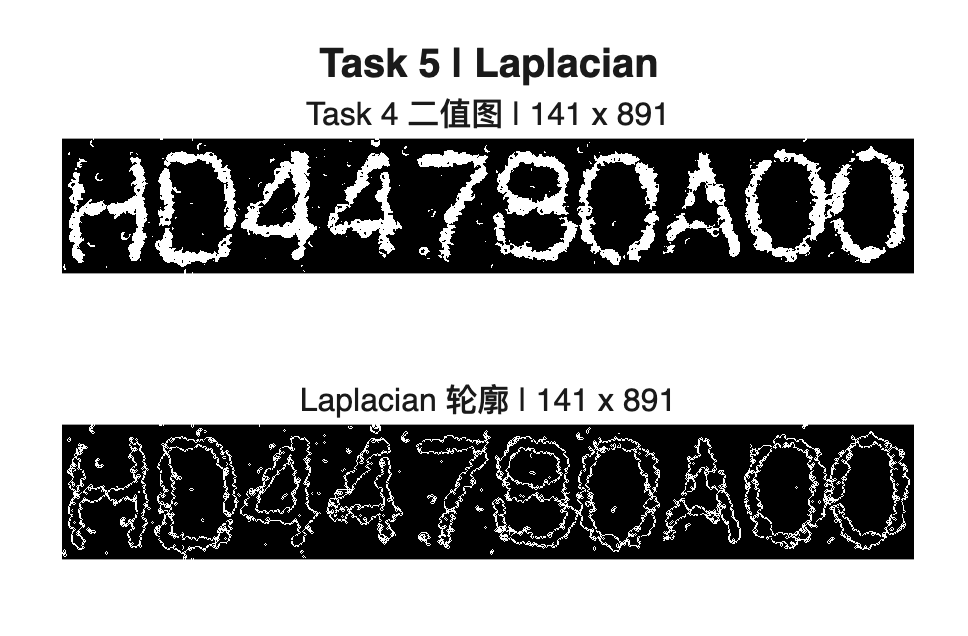


compareImages(I,J,'Task 5 | Laplacian',{'Task 4 二值图','Laplacian 轮廓'},fullfile(runRoot,'Laplacian_comparison.png'));


% 小组观察：________________　小组解释：________________

## Task 5 | Edge Linking

% 输入为本次 TwoPass 轮廓；n 为搜索窗口，magnitudeDifference 为幅值差阈值，directionDifference 为方向差阈值（度）。保留 CoreCode 的 n=5；GUI 默认 n=3。

% 来源：CoreCode/Task5_EdgeLinking.m；以下参数和计算语句保持原稿。

demoExperimentState = me5411_experiment('step',demoExperimentState,13);

I = imread(fullfile(runRoot,'TwoPass.png')) ~= 0;
% 参数（在这里修改）
n = 5;
magnitudeDifference = 0.1;
directionDifference = 20;

demoParameters.EdgeLinking = struct('n',n,'magnitudeDifference',magnitudeDifference,'directionDifference',directionDifference);

[h, w] = size(I);
P = double(I([1, 1:h, h], [1, 1:w, w]));
Gy = conv2(P, [1 2 1; 0 0 0; -1 -2 -1], 'valid');
Gx = conv2(P, [1 0 -1; 2 0 -2; 1 0 -1], 'valid');
M = min(1, hypot(Gx, Gy) / (4 * sqrt(2)));
D = atan2d(Gx, Gy);
J = I;
[h, w] = size(I);
radius = (n - 1) / 2;
for dy = 0:radius
    for dx = -radius:radius
        if dy == 0 && dx <= 0, continue; end
        r = max(1, 1-dy):min(h, h-dy);
        c = max(1, 1-dx):min(w, w-dx);
        if isempty(r) || isempty(c), continue; end
        angle = abs(D(r, c) - D(r+dy, c+dx));
        angle = min(angle, 360-angle);
        accepted = I(r, c) & I(r+dy, c+dx) ...
            & M(r, c) > 0 & M(r+dy, c+dx) > 0 ...
            & abs(M(r, c) - M(r+dy, c+dx)) <= magnitudeDifference ...
            & angle <= directionDifference;
        if max(abs([dy dx])) == 2
            [y, x] = find(accepted);
            y = y + r(1) - 1 + round(dy / 2);
            x = x + c(1) - 1 + round(dx / 2);
            J(sub2ind([h w], y, x)) = true;
        end
    end
end

demoResults.EdgeLinking = J;

demoLog(end+1) = recordResult(runRoot,'Task5','EdgeLinking',I,J);

Task5 / EdgeLinking: [141 891] -> [141 891]; completed.


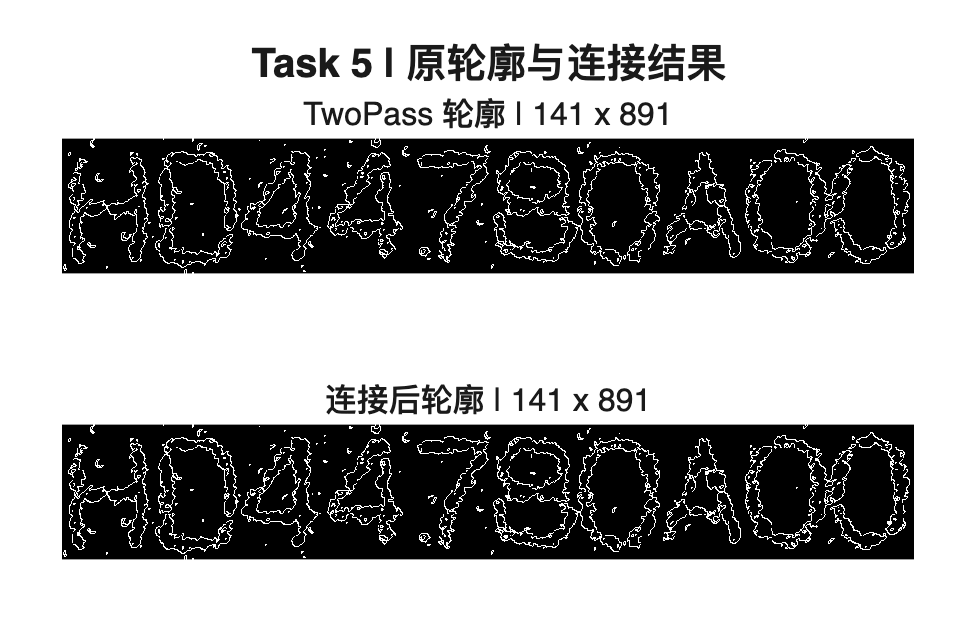


compareImages(I,J,'Task 5 | 原轮廓与连接结果',{'TwoPass 轮廓','连接后轮廓'},fullfile(runRoot,'EdgeLinking_comparison.png'));


% 小组观察：________________　小组解释：________________

## Task 6.1 | Initial Labeling

% 输入直接读取 Task 4 二值图；connectivity=8 表示使用原码的八邻域分支，下面展示完整初始标号关键逻辑。

% 来源：CoreCode/Task6_InitialLabeling.m；以下参数和计算语句保持原稿。

demoExperimentState = me5411_experiment('step',demoExperimentState,14);

I = imread(fullfile(runRoot,'Binarization.png')) ~= 0;
% 参数（在这里修改）
connectivity = 8;

demoParameters.InitialLabeling = struct('connectivity',connectivity);

[height, width] = size(I);
labels = zeros(height, width, 'uint32');
boxes = zeros(0, 4);
centroids = zeros(0, 2);
areas = zeros(0, 1);
totalCount = 0;
if any(I(:))
    provisional = zeros(height, width, 'uint32');
    parents = zeros(nnz(I), 1, 'uint32');
    nextLabel = 0;
    neighbors = zeros(1, 4, 'uint32');
    for row = 1:height
        for column = 1:width
            if ~I(row, column)
                continue;
            end
            neighbors(:) = 0;
            if column > 1
                neighbors(1) = provisional(row, column - 1);
            end
            if row > 1
                neighbors(2) = provisional(row - 1, column);
                if connectivity == 8
                    if column > 1
                        neighbors(3) = provisional(row - 1, column - 1);
                    end
                    if column < width
                        neighbors(4) = provisional(row - 1, column + 1);
                    end
                end
            end
            candidates = neighbors(neighbors ~= 0);
            if isempty(candidates)
                nextLabel = nextLabel + 1;
                parents(nextLabel) = nextLabel;
                provisional(row, column) = nextLabel;
            else
                for index = 1:numel(candidates)
                    root = candidates(index);
                    while parents(root) ~= root
                        root = parents(root);
                    end
                    candidates(index) = root;
                end
                smallest = min(candidates);
                parents(candidates) = smallest;
                provisional(row, column) = smallest;
            end
        end
    end
    roots = zeros(nextLabel, 1, 'uint32');
    for index = 1:nextLabel
        root = uint32(index);
        while parents(root) ~= root
            root = parents(root);
        end
        roots(index) = root;
    end
    foreground = find(I);
    [~, ~, componentIds] = unique(roots(double(provisional(foreground))));
    totalCount = max(componentIds);
    [rows, columns] = ind2sub([height, width], foreground);
    allAreas = accumarray(componentIds, 1, [totalCount, 1]);
    centerX = accumarray(componentIds, columns, [totalCount, 1]) ./ allAreas;
    centerY = accumarray(componentIds, rows, [totalCount, 1]) ./ allAreas;
    allBoxes = [accumarray(componentIds, rows, [totalCount, 1], @min), ...
        accumarray(componentIds, columns, [totalCount, 1], @min), ...
        accumarray(componentIds, rows, [totalCount, 1], @max), ...
        accumarray(componentIds, columns, [totalCount, 1], @max)];
    [~, areaOrder] = sortrows([-allAreas, centerX, centerY, (1:totalCount)']);
    selected = areaOrder;
    mapping = zeros(totalCount, 1, 'uint32');
    mapping(selected) = uint32(1:totalCount);
    labels(foreground) = mapping(componentIds);
    boxes = allBoxes(selected, :);
    centroids = [centerX(selected), centerY(selected)];
    areas = allAreas(selected);
end

initialLabels = labels;
initialBoxes = boxes;
demoResults.InitialLabels = labels;
demoResults.InitialBoxes = boxes;
save(fullfile(runRoot,'Task6_InitialLabeling.mat'),'labels');
writematrix(boxes,fullfile(runRoot,'Task6_InitialLabeling.csv'));
initialRGB = renderExistingLabels(labels,boxes);

demoLog(end+1) = recordResult(runRoot,'Task6','InitialLabeling',I,initialRGB);

Task6 / InitialLabeling: [141 891] -> [141 891 3]; completed.


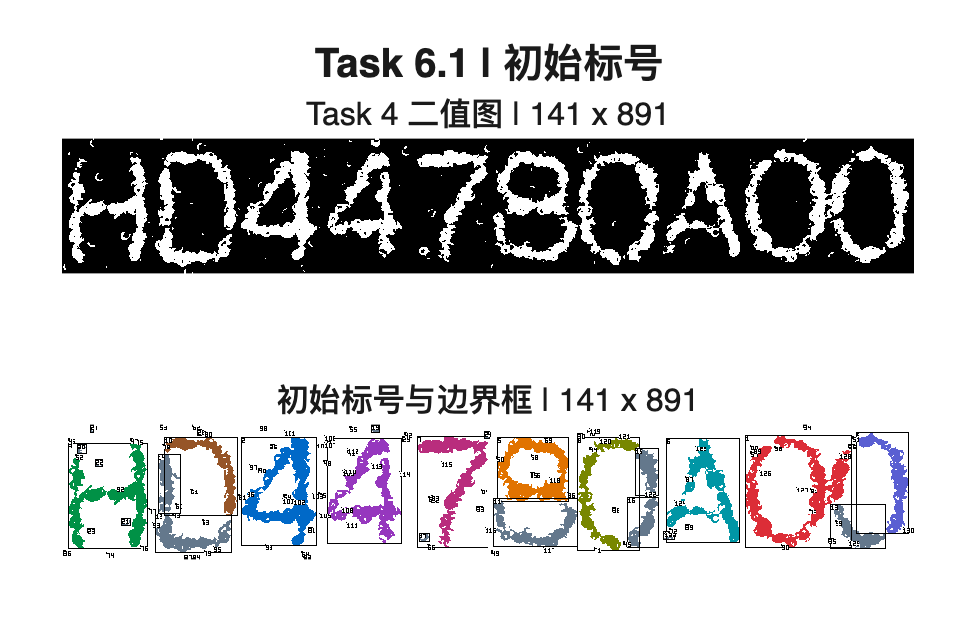

compareImages(I,initialRGB,'Task 6.1 | 初始标号',{'Task 4 二值图','初始标号与边界框'},fullfile(runRoot,'InitialLabeling_comparison.png'));


% 小组观察：________________　小组解释：________________

## Task 6.2 | Check / Cut / Relabel

% expectedWidth 为原码预期字符宽度，tolerance 为容差，单位均为像素；保留窄区域筛选、宽区域切分与重排代码，不代选参数。

% 来源：CoreCode/Task6_CheckCut.m；以下参数和计算语句保持原稿。

demoExperimentState = me5411_experiment('step',demoExperimentState,15);

data = load(fullfile(runRoot,'Task6_InitialLabeling.mat'));
initialLabels = data.labels;
initialBoxes = readmatrix(fullfile(runRoot,'Task6_InitialLabeling.csv'));
% 参数（在这里修改）
expectedWidth = 88;
tolerance = 15;

demoParameters.Relabeling = struct('expectedWidth',expectedWidth,'tolerance',tolerance);

parts = cell(0, 1);
for k = 1:size(initialBoxes, 1)
    b = initialBoxes(k, :);
    mask = initialLabels(b(1):b(3), b(2):b(4)) == k;
    [y, x] = find(mask);
    pixels = [y+b(1)-1, x+b(2)-1];
    width = b(4)-b(2)+1;
    if width < expectedWidth-tolerance, continue; end
    edges = [0; width];
    if width > expectedWidth+tolerance
        count = min(width, max(2, round(width / expectedWidth)));
        nominal = (1:count-1)' * width / count;
        cells = [0; floor((nominal(1:end-1)+nominal(2:end))/2); width-1];
        projection = sum(mask, 1)';
        cuts = zeros(count-1, 1);
        for j = 1:count-1
            first = max([1, round(nominal(j))-tolerance, cells(j)+1]);
            last = min([width-1, round(nominal(j))+tolerance, cells(j+1)]);
            candidates = (first:last)';
            [~, order] = sortrows([projection(candidates), abs(candidates-nominal(j)), candidates]);
            cuts(j) = candidates(order(1));
        end
        edges = [0; cuts; width];
    end
    for j = 1:numel(edges)-1
        part = pixels(x > edges(j) & x <= edges(j+1), :);
        if ~isempty(part) && max(part(:, 2))-min(part(:, 2))+1 >= expectedWidth-tolerance
            parts{end+1, 1} = part;
        end
    end
end
boxes = zeros(numel(parts), 4);
centers = zeros(numel(parts), 2);
for k = 1:numel(parts)
    p = parts{k};
    boxes(k, :) = [min(p(:, 1)), min(p(:, 2)), max(p(:, 1)), max(p(:, 2))];
    centers(k, :) = [mean(p(:, 2)), mean(p(:, 1))];
end
[~, order] = sortrows([centers, boxes(:, 1:2), (1:numel(parts))']);
labels = zeros(size(initialLabels), 'uint32');
for k = 1:numel(parts)
    p = parts{order(k)};
    labels(sub2ind(size(labels), p(:, 1), p(:, 2))) = k;
end
boxes = boxes(order, :);

demoResults.FinalLabels = labels;
demoResults.FinalBoxes = boxes;
save(fullfile(runRoot,'Task6_Relabeling.mat'),'labels');
writematrix(boxes,fullfile(runRoot,'Task6_Relabeling.csv'));
finalRGB = renderExistingLabels(labels,boxes);

demoLog(end+1) = recordResult(runRoot,'Task6','Relabeling',initialLabels,finalRGB);

Task6 / Relabeling: [141 891] -> [141 891 3]; completed.


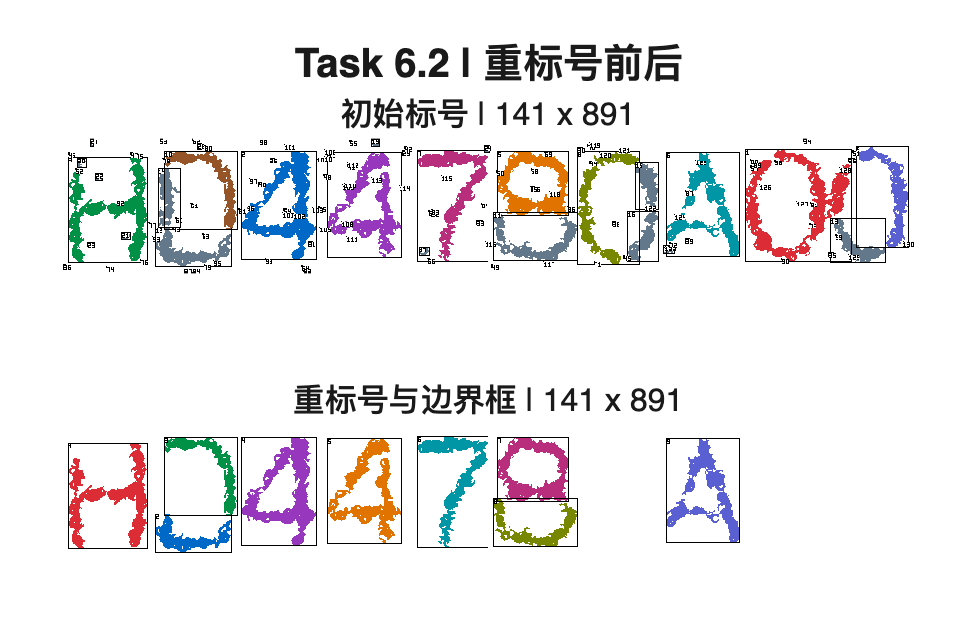

compareImages(initialRGB,finalRGB,'Task 6.2 | 重标号前后',{'初始标号','重标号与边界框'},fullfile(runRoot,'Relabeling_comparison.png'));


% 小组观察：________________　小组解释：________________

## Task 6.3 | Character Crops

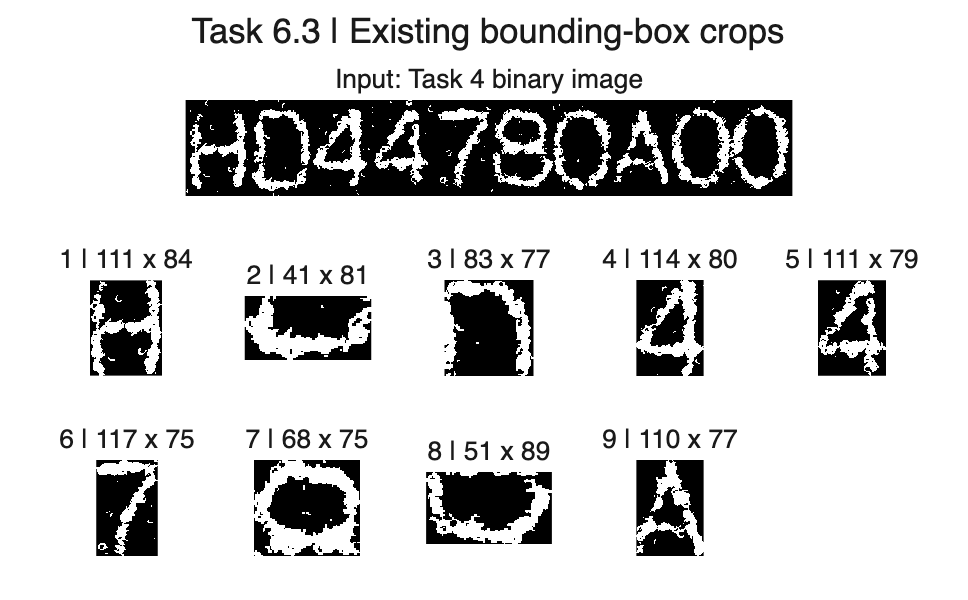

% 按重标号边界框裁剪 Task 4 二值图；这里沿用原码矩形裁剪，不增加逐标号掩膜。字符数量属于程序输出，不自动解释其正确性。

% 来源：CoreCode/Task6_Cut.m；以下参数和计算语句保持原稿。

demoExperimentState = me5411_experiment('step',demoExperimentState,16);

I = imread(fullfile(runRoot,'Binarization.png')) ~= 0;
data = load(fullfile(runRoot,'Task6_Relabeling.mat'));
labels = data.labels;
boxes = readmatrix(fullfile(runRoot,'Task6_Relabeling.csv'));

assert(isequal(size(I), size(labels)), 'Image and label matrix sizes must match.');
regions = double(max(labels(:)));
assert(size(boxes, 1) == regions, 'Bounding boxes must match the region count.');
characters = cell(regions, 1);
for k = 1:regions
    b = boxes(k, :);
    characters{k} = I(b(1):b(3), b(2):b(4));
end

demoResults.Characters = characters;
for k = 1:regions
    imwrite(characters{k},fullfile(runRoot,sprintf('Task6_Character_%d.png',k)));
end
showCharacterCrops(I,characters,fullfile(runRoot,'CharacterCrops_comparison.png'));

fprintf('Task6 Cut: input %d x %d; character crops: %d; completed.\n',size(I,1),size(I,2),regions);

Task6 Cut: input 141 x 891; character crops: 9; completed.


demoLog(end+1) = struct('Task','Task6','Method','CharacterCrops','InputSize',mat2str(size(I)),'OutputSize',sprintf('%d crops',regions),'Status','completed');

% 小组观察：________________　小组解释：________________

## 运行记录与小组填写区

% 下表只记录尺寸与代码完成状态，不提供质量或性能评价。参数快照、数值结果及图像暂存在本轮临时目录；尚未归档。

runTable = struct2table(demoLog);
disp(runTable);

      Task                 Method                 InputSize        OutputSize          Status    
    _________    ___________________________    _____________    _______________    _____________

    {'Task1'}    {'ContrastStretching'     }    {'[367 990]'}    {'[367 990]'  }    {'completed'}
    {'Task1'}    {'GrayLevelSlicing'       }    {'[367 990]'}    {'[367 990]'  }    {'completed'}
    {'Task1'}    {'DynamicRangeCompression'}    {'[367 990]'}    {'[367 990]'  }    {'completed'}
    {'Task1'}    {'HistogramEqualization'  }    {'[367 990]'}    {'[367 990]'  }    {'completed'}
    {'Task2'}    {'MeanFiltering'          }    {'[367 990]'}    {'[367 990]'  }    {'completed'}
    {'Task2'}    {'RotatingMask'           }    {'[367 990]'}    {'[367 990]'  }    {'completed'}
    {'Task2'}    {'MedianFiltering'        }    {'[367 990]'}    {'[367 990]'  }    {'completed'}
    {'Task3'}    {'Crop'                   }    {'[367 990]'}    {'[141 891]'  }    {'completed'}
    {'Task4'}    {'

writetable(runTable,fullfile(runRoot,'run-status.csv'));
save(fullfile(runRoot,'results.mat'),'demoResults','demoParameters','demoLog');
fid = fopen(fullfile(runRoot,'parameters.json'),'w');
fprintf(fid,'%s',jsonencode(demoParameters,PrettyPrint=true)); fclose(fid);
fprintf('ME5411_DEMO_COMPLETE: %s\n',demoExperimentState.RunId);

ME5411_DEMO_COMPLETE: tp936ba4ae_df2e_46f4_b53c_9f74e111d86a



demoExperimentState = me5411_experiment('complete',demoExperimentState);

% 小组最终使用的参数及理由：________________

% 小组对各方法的观察、分析与解释：________________

% 运行日期 / 小组成员 / 备注：________________

## 保存本次实验

% 先从头运行并查看图像；要归档，把下方 false 改为 true，填写名称或备注，仅运行本节。不保存就保持 false。

% 归档读取本轮已经执行的参数与图像快照；仅编辑参数但未重跑，不会改变该快照。修改计算参数后请从头运行。

% 保存 MATLAB 文档（Cmd+S）与归档实验是两件事；本节只归档实验数据。临时中间文件会保留到系统清理，旧归档不会删除。

saveExperiment = false; % false：不归档；true：归档这次已完成的结果。
experimentName = ""; % 可填简短实验名称。
experimentNotes = ""; % 可填备注；记录在 archive-info.json。
if ~exist('demoExperimentState','var')
    demoExperimentState = struct('Completed',false);
end
archiveResult = me5411_experiment('archive',demoExperimentState,saveExperiment,experimentName,experimentNotes);

未归档；图像仍可查看，中间文件暂存在本轮临时目录。


## 辅助函数（积分和与显示 / 记录）

% makeSummedArea、squareWindowSums 原样取自 Task2_MeanFiltering.m（RotatingMask 中定义相同）。renderExistingLabels 的标号图绘制取自 Task6_InitialLabeling.m；其余函数只负责版面、文件与尺寸记录。

function summedArea = makeSummedArea(pixels)
    summedArea = zeros(size(pixels) + 1);
    summedArea(2:end, 2:end) = cumsum(cumsum(pixels, 1), 2);
end

function sums = squareWindowSums(summedArea, width)
    sums = summedArea((width + 1):end, (width + 1):end) ...
        - summedArea(1:(end - width), (width + 1):end) ...
        - summedArea((width + 1):end, 1:(end - width)) ...
        + summedArea(1:(end - width), 1:(end - width));
end

function rgb = renderExistingLabels(labels,boxes)
palette = uint8([255 255 255; 220 45 55; 0 105 200; 0 145 70; ...
    150 55 190; 225 115 0; 0 150 165; 185 45 125; 120 135 0; ...
    90 95 210; 150 85 40; 100 120 140]);
rgb = reshape(palette(min(double(labels(:)), 11) + 1, :), [size(labels), 3]);
for k = 1:size(boxes, 1)
    b = boxes(k, :);
    rgb([b(1), b(3)], b(2):b(4), :) = 0;
    rgb(b(1):b(3), [b(2), b(4)], :) = 0;
end
glyphs = {'111101101101111', '010110010010111', '111001111100111', ...
    '111001111001111', '101101111001001', '111100111001111', ...
    '111100111101111', '111001001001001', '111101111101111', '111101111001111'};
for k = 1:size(boxes, 1)
    digits = sprintf('%d', k);
    mask = false(5, 4 * numel(digits) - 1);
    for d = 1:numel(digits)
        mask(:, 4*(d-1)+(1:3)) = reshape(glyphs{digits(d)-'0'+1} == '1', 3, 5)';
    end
    y = max(1, min(boxes(k, 1)+1, size(labels, 1)-4));
    x = max(1, min(boxes(k, 2)+1, size(labels, 2)-size(mask, 2)+1));
    r = y:min(size(labels, 1), y+4);
    c = x:min(size(labels, 2), x+size(mask, 2)-1);
    rgb(r, c, :) = repmat(uint8(~mask(1:numel(r), 1:numel(c))) * 255, 1, 1, 3);
end
end

function record = recordResult(runRoot,task,method,input,output)
assert(~isempty(input) && ~isempty(output),'Empty input or output');
imwrite(output,fullfile(runRoot,[method '.png']));
record = struct('Task',task,'Method',method,'InputSize',mat2str(size(input)), ...
    'OutputSize',mat2str(size(output)),'Status','completed');
fprintf('%s / %s: %s -> %s; completed.\n',task,method,record.InputSize,record.OutputSize);
end

function compareImages(before,after,heading,captions,path)
f = figure('Name',heading,'Color','w','Position',[80 80 1050 690]);
layout = tiledlayout(f,2,1,'TileSpacing','compact','Padding','compact');
for index=1:2
    if index==1, pixels=before; else, pixels=after; end
    ax = nexttile(layout);
    if ndims(pixels)==3
        image(ax,pixels);
    elseif islogical(pixels)
        imagesc(ax,pixels,[0 1]);
    else
        imagesc(ax,pixels,[0 255]);
    end
    axis(ax,'image'); axis(ax,'off');
    title(ax,sprintf('%s | %d x %d',captions{index},size(pixels,1),size(pixels,2)),'FontSize',12,'Color',[0.1 0.1 0.1]);
end
colormap(f,gray(256)); title(layout,heading,'FontSize',15,'FontWeight','bold','Color',[0.1 0.1 0.1]);
exportgraphics(f,path,'Resolution',120);
end

function showCharacterCrops(input,characters,path)
f = figure('Name','Task 6.3 | Character Crops','Color','w','Position',[80 80 1050 650]);
count=numel(characters); columns=5; rows=1+max(1,ceil(count/columns));
layout=tiledlayout(f,rows,columns,'TileSpacing','compact','Padding','compact');
ax=nexttile(layout,[1 columns]); imagesc(ax,input,[0 1]); axis(ax,'image'); axis(ax,'off');
title(ax,'Input: Task 4 binary image','Color',[0.1 0.1 0.1]);
for index=1:count
    ax=nexttile(layout); imagesc(ax,characters{index},[0 1]); axis(ax,'image'); axis(ax,'off');
    title(ax,sprintf('%d | %d x %d',index,size(characters{index},1),size(characters{index},2)),'Color',[0.1 0.1 0.1]);
end
colormap(f,gray(256)); title(layout,'Task 6.3 | Existing bounding-box crops','Color',[0.1 0.1 0.1]);
exportgraphics(f,path,'Resolution',120);
end